# Rotation (orientation)

The DICOM  `ImageOrientationPatient` contains 6 elements: a 3D vector that points along an image row, and a second that points down a column. Both are unit vectors in the Left-Posterior-Head (LPH) patient coordinate system.

These vectors are sometimes called direction cosines because the numerical value in each element is just the cosine of the angle the vector makes with the corresponding L, P or H axis. These values are also the dot product of the vector with each of these axes.

The 6-element IOP vector is `iop = [rL rP rH cL cP cH] `with the through-slice direction `[sL sP sH ] `given by `cross( iop(1:3), iop(4:6) ).` It is more reliable to use this vector that the DICOM `SliceNumbering` field.

The relation between intrinsic image coordinates `[i j k]` and LPH coordinates` [L P H]` is then (ignoring origin positions and pixel sizes):


$${\rm [ L \ P \ H ] = [ i \ j \ k] * \left[ {\begin{array}{cc}
rL & rP & rH \\
cL & cP & cH \\
sL & sP & sH \\
\end{array} } \right]}$$


Each of the values L, P and H is the scalar (dot) product of `[i j k]` with the corresponding column of the matrix.

From this we see how the DICOM `ImageOrientationPatient` describes a rotation, or orientation. In more detail.

The Intrinsic Coordinate System used by MATLAB to represent an array as an image has the centre of the top left pixel as (1,1) and y increases down a column.

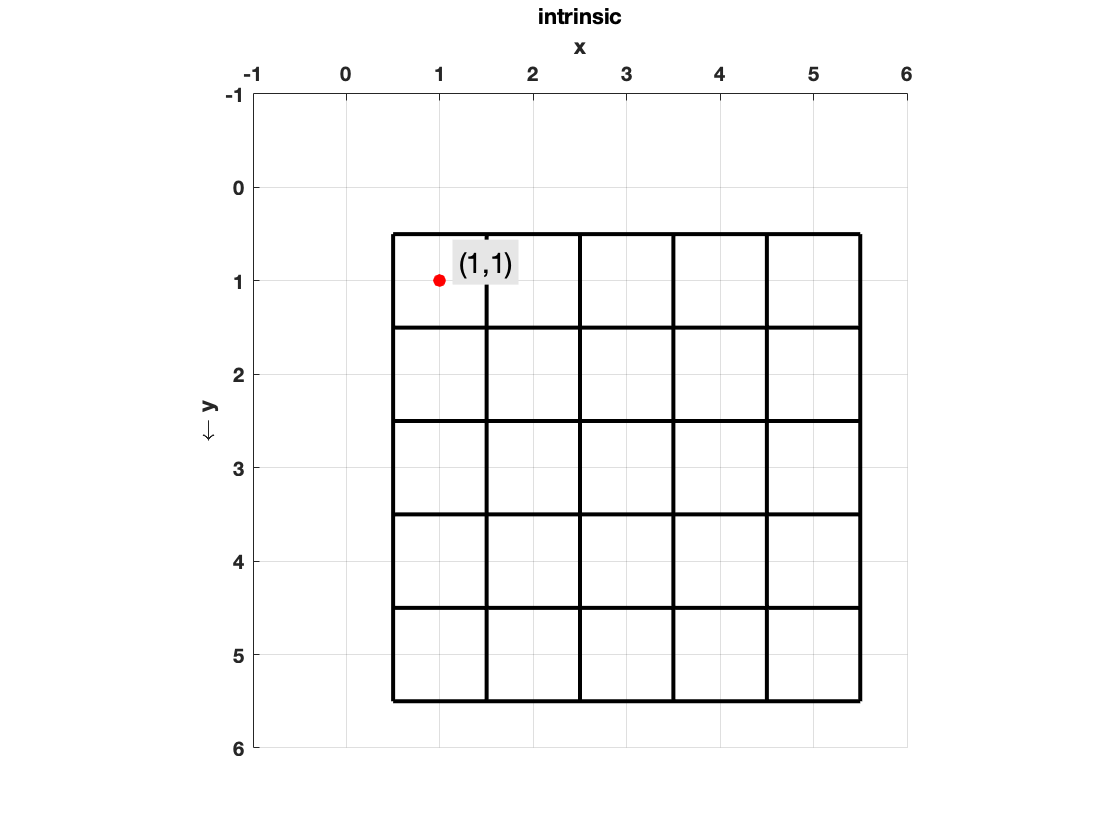

draw_image('intrinsic')

The DICOM fields that are needed to specify the location of an image pixel in LPH space are depicted here:

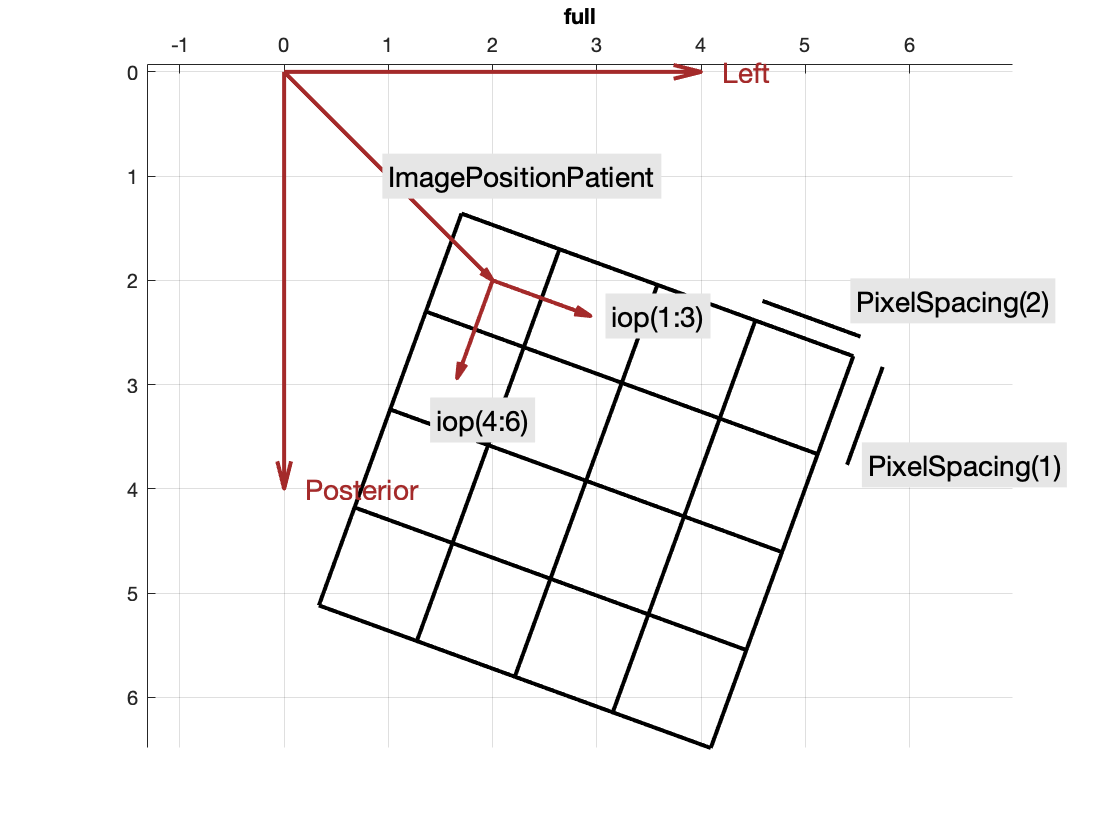

draw_image('full')

If we put all the origins at the centre of the top left pixel and assume pixels of size 1, then we can more clearly see the link between `ImageOrientationPatient` and rotations. 

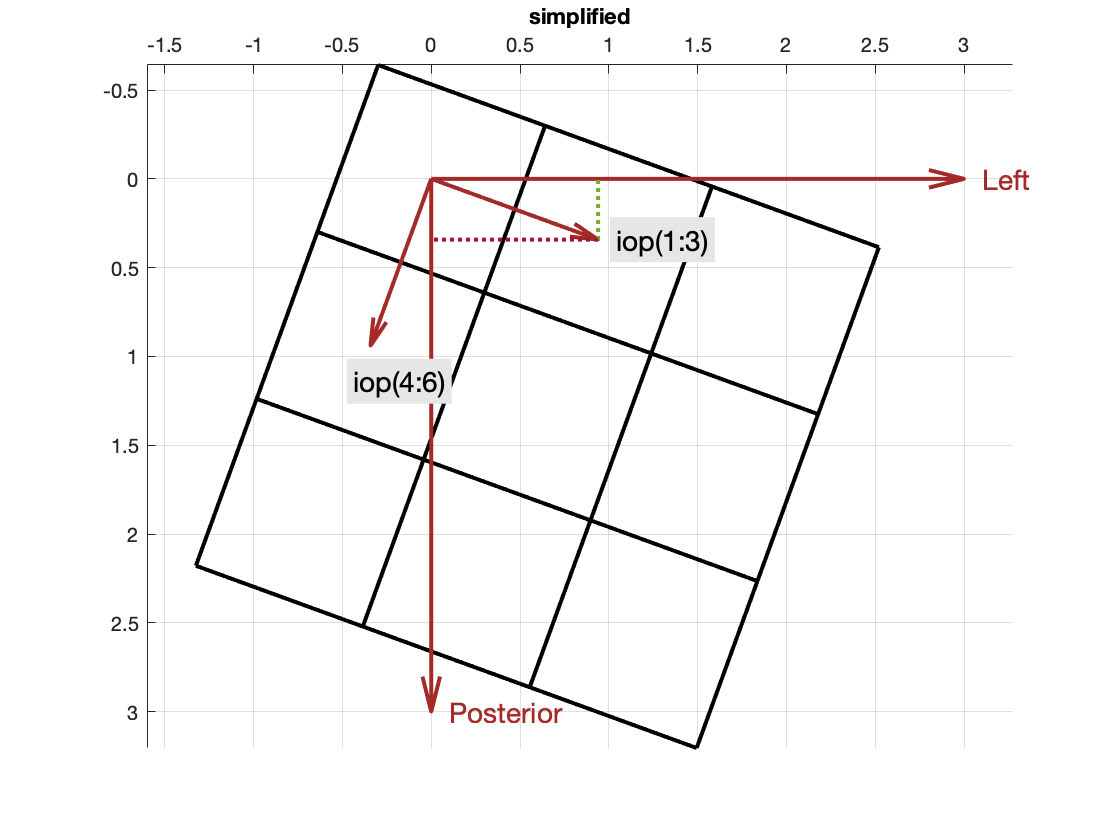

draw_image('simplified')

In this figure, the iop vector is

`[ cosd(theta) sind(theta)  0 -sind(theta) cosd(theta) 0] `

which tie up with the earlier description in this live script.